# Todo/SP_Localization

**List of to do:**

close all
clear

**1- Pose estimated: **A figure of a noisy trajectory with the ellipses representing the covariance error in position. Make a zoom in to see in detail.

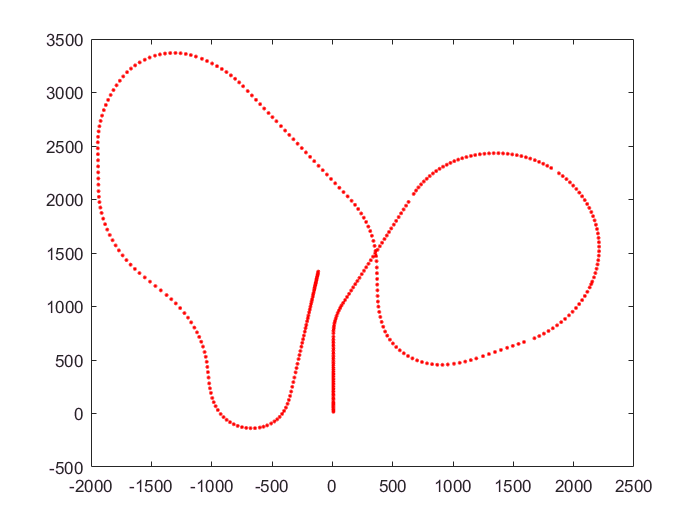


load('Work_Space_Localization_Short_project.mat');

Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]';% The Robot icon is a triangle
data = data_enc;

for index=2:522 % Use the for loop to see a movie
    R1 = data(index,7);
    L1 = data(index,6);
    R0 = data(index-1,7);
    L0 = data(index-1,6);
    Rmio(index,1) = data_enc(index,1);
    Rmio(index,2) = R1-R0;
    Lmio(index,1) = data_enc(index,1);
    Lmio(index,2) = L1-L0;
end

%Inicializamos

ts=0.02; 
S = 243/2;

IC = [8.65,17.2,-pi/2];
x_ini=IC(1);
y_ini=IC(2);
theta_ini=IC(3);

x_w=x_ini;
y_w=y_ini;
suma_theta=-theta_ini; 

ProcNoiseD = [0.000100000000000000];
ProcNoiseTheta = [1.00000000000000e-06];
V=[ProcNoiseD 0;0 ProcNoiseTheta];
    
for index=1:522
    delta_th = ((Rmio(index,2)-Lmio(index,2))/(2*S));
    delta_d = (Rmio(index,2)+Lmio(index,2))/2;
    
    x_w = x_w + (delta_d + V(1,1))*cos(suma_theta + delta_th + V(2,2));
    y_w = y_w + (delta_d + V(1,1))*sin(suma_theta + delta_th + V(2,2));
    suma_theta=mod((suma_theta + delta_th + V(2,2)) ,2*pi); 
    
    matrix_pose(index,1) = x_w;
    matrix_pose(index,2) = y_w;
    matrix_pose(index,3) = suma_theta;
    
    traj(index,1) = x_w;
    traj(index,2) = y_w;
    traj(index,3) = suma_theta;

end

plot (traj(:,1), traj(:,2), 'r.','LineWidth',1.5); % Plotting the trajectory 

**2- Polar 2 Cartesian: **A figure of the Land Mark seeing in Robot Reference Frame.

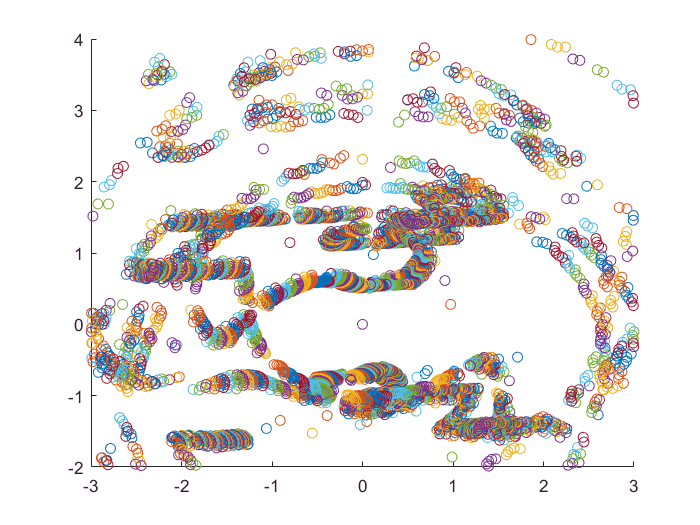

close all

%Apartado 2

%Pasamos las distancias de polar a cartesianas, para obtener las X e Y de
%las landmarks en el reference frame del robot
for i=1:523
    for j=2:361
        ldx_RFr(i,j) = (lds_dis(i,j)*cosd(j))/1000;
        ldy_RFr(i,j) = (lds_dis(i,j)*sind(j))/1000;
    end
end

%Plot landmarks en el reference frame del robot
for k=1:522
    scatter(ldx_RFr(k,:), ldy_RFr(k,:));
    axis([-3 3 -2 4]); 
    hold on;
end

**3- Robot to World: **Generate the workspace 'laserW' variable and include in the report a figure of the Land Mark seeing in World Reference Frame.

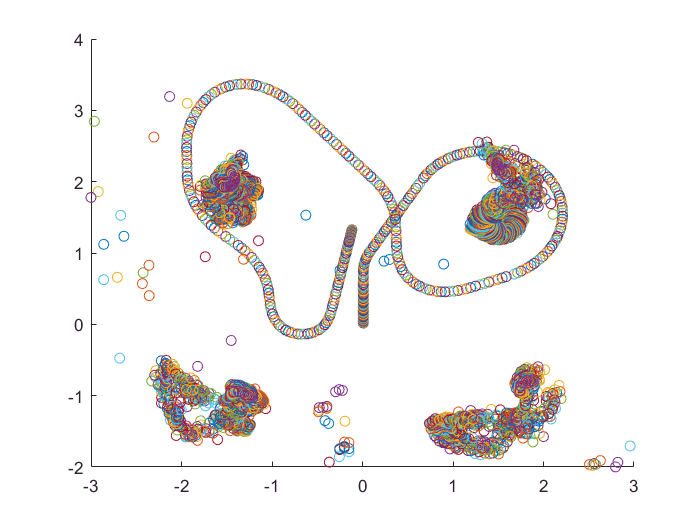

close all

%Apartado 3

%Calculo ldx y ldy pasamos del RF del robot al RF del mundo
for i=1:522
    Tw_r = transl(matrix_pose(i,1)/1000, matrix_pose(i,2)/1000,0)*trotz(matrix_pose(i,3));
    
    for j=1:360
        aux = Tw_r*[ldx_RFr(i,j); ldy_RFr(i,j); 0; 1];
        ldx_RFw(i,j) = aux(1);
        ldy_RFw(i,j) = aux(2);
    end
end

%Prueba si va el RFw
for k=1:522
    scatter( ldx_RFw(k,:), ldy_RFw(k,:));
    axis([-3 3 -2 4]); 
    hold on;
end

**4- Associated Land Mark: **Filter out the lidar data by detecting the landMark (datacloud) and Identifying the LandMark (nearest_to). Add to the report a figure with colored Land Mark seeing by the Robot.

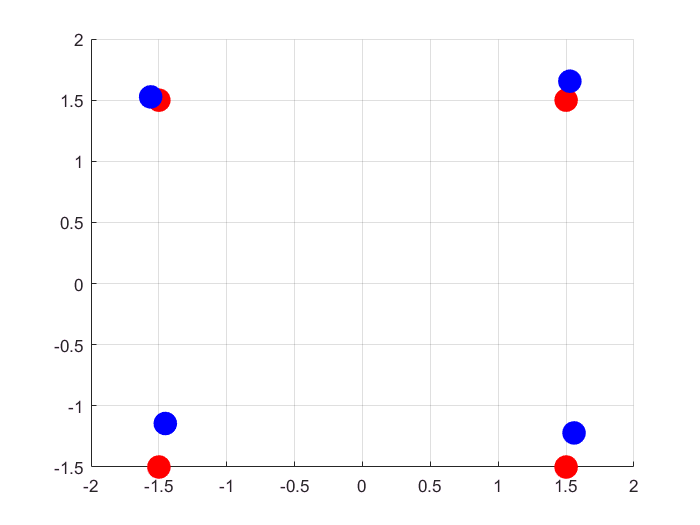

close all

%Apartado 4

%Filtro de las landmarks, eliminamos las que no corresponden a un landmark
%real
xcount_u_r = 0;
xcount_d_r = 0;
xcount_u_l = 0;
xcount_d_l = 0;

ycount_u_r = 0;
ycount_d_r = 0;
ycount_u_l = 0;
ycount_d_l = 0;

xsum_u_r = 0;
xsum_d_r = 0;
xsum_u_l = 0;
xsum_d_l = 0;

ysum_u_r = 0;
ysum_d_r = 0;
ysum_u_l = 0;
ysum_d_l = 0;

for i=1:522
    for j=1:360
        %Arriba derecha (ur)
        if (ldx_RFw(i,j) > (0.5) && ldx_RFw(i,j) < (2.5)) && (ldy_RFw(i,j) > (0.5) && ldy_RFw(i,j) < (2.5))
            xcount_u_r = xcount_u_r + 1;
            xsum_u_r = xsum_u_r + ldx_RFw(i,j);
            
            ycount_u_r = ycount_u_r + 1;
            ysum_u_r = ysum_u_r + ldy_RFw(i,j);
            
        %Abajo derecha (dr)
        elseif (ldx_RFw(i,j) > (0.5) && ldx_RFw(i,j) < (2.5)) && (ldy_RFw(i,j) < (-0.5) && ldy_RFw(i,j) > (-2.5))
            xcount_d_r = xcount_d_r + 1;
            xsum_d_r = xsum_d_r + ldx_RFw(i,j);
            
            ycount_d_r = ycount_d_r + 1;
            ysum_d_r = ysum_d_r + ldy_RFw(i,j);
            
        %Abajo izquierda (dl)
        elseif (ldx_RFw(i,j) < (-0.5) && ldx_RFw(i,j) > (-2.5)) && (ldy_RFw(i,j) < (-0.5) && ldy_RFw(i,j) > (-2.5))
            xcount_d_l = xcount_d_l + 1;
            xsum_d_l = xsum_d_l + ldx_RFw(i,j);
            
            ycount_d_l = ycount_d_l + 1;
            ysum_d_l = ysum_d_l + ldy_RFw(i,j);
            
        %Arriba izquierda (ul)
        elseif (ldx_RFw(i,j) < (-0.5) && ldx_RFw(i,j) > (-2.5)) && (ldy_RFw(i,j) > (0.5) && ldy_RFw(i,j) < (2.5))
            xcount_u_l = xcount_u_l + 1;
            xsum_u_l = xsum_u_l + ldx_RFw(i,j);
            
            ycount_u_l = ycount_u_l + 1;
            ysum_u_l = ysum_u_l + ldy_RFw(i,j);   
        end  
    end
end

%Medias
% X
landmarks_nuestras(1,1) = xsum_u_r/xcount_u_r;
landmarks_nuestras(1,2) = xsum_d_r/xcount_d_r;
landmarks_nuestras(1,3) = xsum_u_l/xcount_u_l;
landmarks_nuestras(1,4) = xsum_d_l/xcount_d_l;
% Y
landmarks_nuestras(2,1) = ysum_u_r/ycount_u_r;
landmarks_nuestras(2,2) = ysum_d_r/ycount_d_r;
landmarks_nuestras(2,3) = ysum_u_l/ycount_u_l;
landmarks_nuestras(2,4) = ysum_d_l/ycount_d_l;

%Landmarks originales
LandMark = [  1.5,1.5; -1.5,1.5; -1.5,-1.5;  1.5, -1.5]'; 
figure 
axis ([-2 2 -2 2]) 
scatter(LandMark(1,:),LandMark(2,:),200, 'r','filled'); 
grid on;
hold on;
%Plot landmarks nuestras en FR world
scatter(landmarks_nuestras(1,:),landmarks_nuestras(2,:),200, 'b','filled');

**5- Similarity Transform: **Adapt the Similarity Transform to output the error in pose given a time.


%Build Matrix A 
A = []; 
for i=1:size( LandMark , 2)     
    A = [A;[ LandMark(1,i), LandMark(2,i),1,0]];     
    A = [A;[ LandMark(2,i),-LandMark(1,i),0,1]]; 
end

%Build Matrix B 
B = [];
for i=1:size( landmarks_nuestras , 2)     
    B = [B;  landmarks_nuestras(1,i);  landmarks_nuestras(2,i)]; 
end

%Compute tx ty i tita 
X = inv((A'*A))*A'*B  %X = (A'*A)\A'*B;

X =     0.0107
    0.4911
    0.0182
    0.2040


Tx_ST = X(3) 

Tx_ST = 0.0182

Ty_ST= X(4) 

Ty_ST = 0.2040

alpha_ST = atan2(X(2),X(1));%*180/pi

%Rotamos y transladamos nuestras landmarks
matriz_correccion = trotz(alpha_ST)*transl(Tx_ST,Ty_ST,0)

matriz_correccion =     0.0218   -0.9998         0   -0.2035
    0.9998    0.0218         0    0.0226
         0         0    1.0000         0
         0         0         0    1.0000


landmarks_corregidas = landmarks_nuestras*matriz_correccion; 


**Ejecutable final:**


Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]';% The Robot icon is a triangle 

for index=1:522 % Use the for loop to see a movie
    t = 0: 2*pi/359 : 2*pi; 
    P = polar(t, 4.5 * ones(size(t)));% to fix the limits 
    set(P, 'Visible', 'off') 
    subplot(1,2,1) 
    polar(t, lds_dis (index,2:361), '--g'); % Ploting the laser data wrt Robot frame 
    title ('Laser data at Robot vReference Frame','FontWeight','bold','FontSize',16) 
    subplot(1,2,2) 
    title ('Data on Wordl Reference Frame', 'FontWeight','bold','FontSize',16) 
    axis([-3 3 -2 4]) 
    grid on 
    hold on 
    for i=1:4 % plotting the 4 Land Marks 
        circle (LandMark(i,:)',0.15) 
    end
    scatter(ldx(index,:), ldy(index,:)) % plotting the land mark seen by the Robot wrt  wordl reference frame
    plot (trajec(:,1), trajec(:,2), 'r.','LineWidth',1.5) % Plotting the trajectory 
    Robot_tr=transl(trajec(index,1),trajec(index,2),0)*trotz(mod(trajec(index,3)+pi/2,2*pi))*Robot;% moving the robot 
    patch(Robot_tr(1,:), Robot_tr(2,:),'b');
    plot_ellipse(pk.signals.values(1:2,1:2,index),[trajec(index,1), trajec(index,2)],'g'); % Plotting the covariance matrix 
    pause(0.1); 
    clf
end
